# Gridded NORA3 data: Getting a time series from an offshore location

The second example introduces an alternative way to extract hourly data in terms of time series, from one location. Additional data are also included in the data extraction, in terms of optional parameters. The data source is still [2].

Notes:

- Dont use the present code in complex terrain, were the interpolation scheme will not be reliable. 

- The present implementation for the temperature profile is not yet validated and could contain some errors

References

[2] [https://thredds.met.no](https://thredds.met.no/)  

## Definition of the parameters

Some days in April 2016 in the North Sea

clearvars;close all;clc;

targetDate = datetime(2016,04,10,0,0,0):duration(1,0,0):datetime(2016,04,12,0,0,0);
resolution = 0.025; % resolution for latitude and longitude in degrees (< 3 km)
targetLat = [54.014861]; % target latitude
targetLon = [6.587639];  % target longitude
N = numel(targetDate)

N = 49

Nz = 7; % heights levels
Np = 16; % presure levels
Nlat = numel(targetLat);
Nlon = numel(targetLon);


U = NaN(N,Nlat,Nlon,Nz); %  Mean wind speed profile
D = NaN(N,Nlat,Nlon,Nz); %  Mean wind direction profile
T = NaN(N,Nlat,Nlon,Np); %  Temperature of the air
T0 = NaN(N,Nlat,Nlon); %  Temperature of the air at the surface
zT = NaN(N,Np); %  Height for Temperature profile estimated using barometric formula
time = NaT(1,N);


for ii=1:N
    targetYear = num2str(year(targetDate(ii)));
    targetMonth = num2str(month(targetDate(ii)));
    targetDay = num2str(day(targetDate(ii)));
    targetHour = num2str(hour(targetDate(ii)));   
    tic
    [mydata] = getNORA3(targetLat,targetLon,targetYear,targetMonth,targetDay,targetHour,resolution,'optPara','T');
    toc
    
    zT(ii,:)= mydata.zT; % depends n surface pressure and surface temperature
    T(ii,:,:,:)= mydata.T;
    T0(ii,:,:)= mydata.T0;
    U(ii,:,:,:)= mydata.U;
    D(ii,:,:,:) = mydata.D;
    time(ii)= mydata.time;
    
end

Elapsed time is 7.161654 seconds.
Elapsed time is 7.074751 seconds.
Elapsed time is 6.734277 seconds.
Elapsed time is 6.449950 seconds.
Elapsed time is 7.475620 seconds.
Elapsed time is 6.782260 seconds.
Elapsed time is 6.888414 seconds.
Elapsed time is 6.675626 seconds.
Elapsed time is 7.005097 seconds.
Elapsed time is 6.336719 seconds.
Elapsed time is 6.467820 seconds.
Elapsed time is 6.790629 seconds.
Elapsed time is 6.300771 seconds.
Elapsed time is 6.688336 seconds.
Elapsed time is 6.068494 seconds.
Elapsed time is 6.936033 seconds.
Elapsed time is 6.276109 seconds.
Elapsed time is 6.557030 seconds.
Elapsed time is 6.679986 seconds.
Elapsed time is 6.285337 seconds.
Elapsed time is 6.249802 seconds.
Elapsed time is 6.291994 seconds.
Elapsed time is 6.116219 seconds.
Elapsed time is 6.203230 seconds.
Elapsed time is 5.911218 seconds.
Elapsed time is 6.691665 seconds.
Elapsed time is 6.110689 seconds.
Elapsed time is 6.653854 seconds.
Elapsed time is 6.918680 seconds.
Elapsed time i


z = mydata.z;

## Visualisation of the results

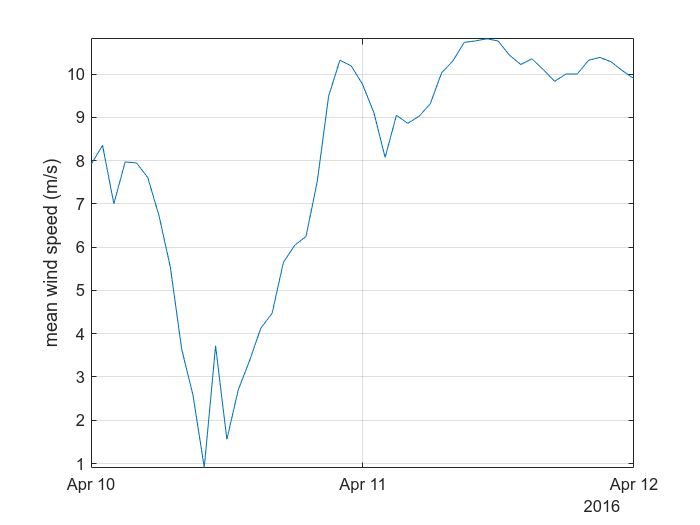

clf;close all
figure
plot(time, squeeze(U(:,:,:,1)))
grid on
ylabel('time')
ylabel('mean wind speed (m/s)')
axis tight

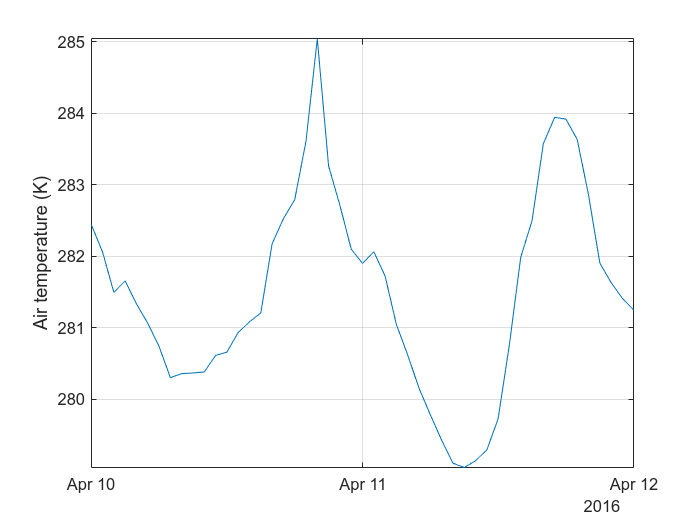


clf;close all
figure
plot(time, squeeze(T(:,:,:,1)))
grid on
ylabel('time')
ylabel('Air temperature (K)')
axis tight



figure
indN = 19:2:32;
COLOR = parula(numel(indN));
clear leg pl
ll=1;
for ii=indN
    
    % Interpolate the profiles
    oldZ = mydata.z;
    oldU = squeeze(U(ii,:,:,:)); % old wind speed profile from the NORA3 database
    newZ = logspace(log10(oldZ(1)),log10(oldZ(end)),100); % new hright vector with logarithmic spacing
    [z0] = getz0_charnock(oldU(1),oldZ(1),0.016); % Get the roughness of the sea by solving Charnock's equation
    u_star = oldU(1)*0.4./log(oldZ(1)./z0);  % frictionv velocity estimated with the logarithmic mean wind speed profile
    [newU,rmse] = interpU(oldZ,z0,oldU,newZ,u_star);
    
    
    pl(ll) = plot(newU,newZ,'color',COLOR(ll,:));
    hold on
    box on
    grid on
    plot(oldU,oldZ,'o','color',COLOR(ll,:));
    leg{ll} = datestr(time(ii));
    ll=ll+1;
end

Charnock relationship leads to zsea = 7.1e-05 m 
Charnock relationship leads to zsea = 1.2e-04 m 
Charnock relationship leads to zsea = 2.6e-04 m 
Charnock relationship leads to zsea = 2.3e-04 m 
Charnock relationship leads to zsea = 1.4e-04 m 
Charnock relationship leads to zsea = 1.8e-04 m 
Charnock relationship leads to zsea = 2.0e-04 m 


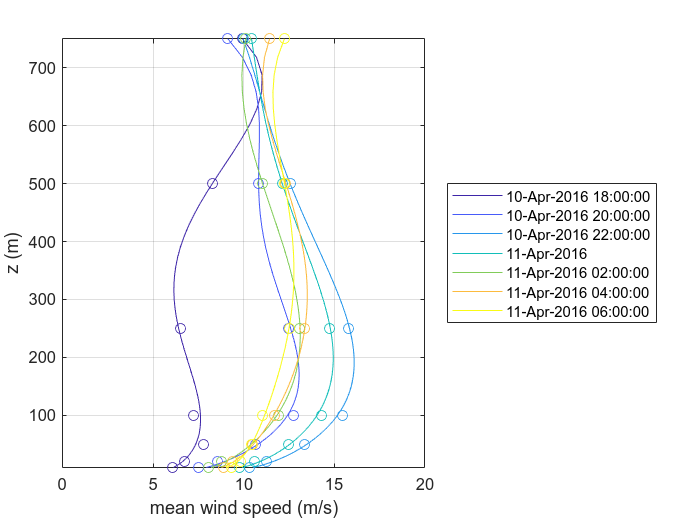

ylabel('z (m)')
xlabel('mean wind speed (m/s)')
axis tight
xlim([0 20])
legend(pl,leg{:},'location','eastoutside')

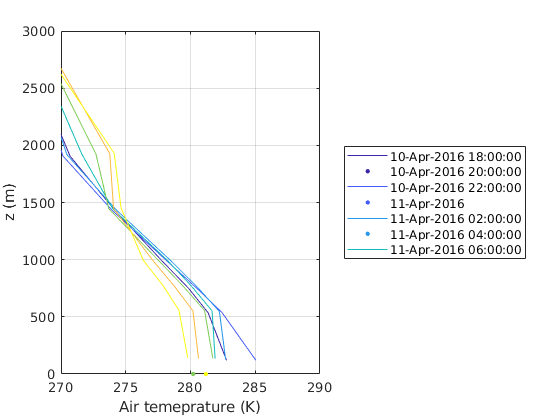


figure
indN = 19:2:32;
COLOR = parula(numel(indN));
clear leg pl
ll=1;
for ii=indN
    plot(squeeze(T(ii,:,:,:)), zT(ii,:),'color',COLOR(ll,:));
    hold on
    plot(squeeze(T0(ii,:,:)), 0,'.','color',COLOR(ll,:),'markersize',10);
    box on
    grid on
    leg{ll} = datestr(time(ii));
    ll=ll+1;
end
ylabel('z (m)')
xlabel('Air temeprature (K)')
axis tight
xlim([270 290])
ylim([0,3000])
legend(leg{:},'location','eastoutside')